# **Controls for parameter tuning**

Linear classification

Holdout 50 or 80% --> community uses 80%

 --> maybe check a few cells

============

OBSERVATIONS

============

Analysis on MODULATION

==> WHAT NOT JUST THE PEAKS (full signal)

-  Encoder

-  EyeCam_Wheel --> check against encoder

-  L Forelimb

-  R Forelimb

-  Trunk (highest for 3-4 cells, so keep for now)

-  BodyCam LWhisker : The good one (behind, on black background)

- BodyCam RWhisker (on the whiskerpad, from the front + cuetip)

- Perioral

- trigger

- F0

Excluded : 

- Laser

- BodyCam Eye --> meh

- Eycam whiskerpad (just check 09-12 exp 9-11 exp2 04-30-exp4

- eyecam Eye (check 09-04 exp2)

- NOT RT3D_MC BUT BASELINE F0 instead

============

PREDICTORS

============

* All ROIs

* Highest PHATE (+ and - for PHATEs 1-3)

* Perisomatic ROIS (6)

* 6 random ROIs 

* High PHATES GROUPS (6 ROIs of the PHATES 1->3 + and -)

# 1. Load experiment

You can use this script as a standalone function. In this case, indicate the path to an extracted arboreal_scan folder, or to an arboreal_scan_experiment mat file here

path_to_use = 'C:\Users\Antoine.Valera\MATLAB\newextraction_raw_zscored\2019-10-01_exp_1';

You can use this script in a loop. To do this, 

- create a variable called use_existing and set it to true.

- create a loop with the exported experiment path called expe_folder. 

The expe_folder path can point to

- an extracted expe_folder, in this case the arboreal_scan_experiment object will be generated and saved. If expe_folder contains an exisiting arboreal_scan_experiment, the code will ask you want to do, which will pause the excution of the loop.

- an arboreal_scan_experiment object (faster)

if exist('use_existing','var') && use_existing == true && exist('expe_folder','var') && ischar(expe_folder)
    path_to_use = expe_folder
elseif exist('use_existing','var')
    error('to use this script in a loop, read the procedure explained in the code')    
end

obj = arboreal_scan_experiment(path_to_use);


if contains(path_to_use,'.mat')
    folder_to_use = parse_paths(fileparts(path_to_use));
else
    folder_to_use = path_to_use;
end


# 2. Define the Analysis Settings

## Arboreal Scan settings

obj.detrend                         = 0;            % -1; %'auto'
obj.rendering                       = 0;
obj.filter_win                      = [-1.5, 0];

## Behaviour Settings

behaviours                          = {'encoder','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger'};
obj.beh_smoothing                   = [-1.5, 0];
obj.beh_sm_func                     = 'gaussian'
obj.shuffling_block_size            = -3;
obj.detrend_behaviour               = false;

phase = 'puff' % any in '', 'whisker','free', 'puff' 
if ~isempty(phase)
    phase           = 'puff';
    in_phase        = cellfun(@(x) any(contains(x, phase,'IgnoreCase',true)), obj.logs); % puff, free, whisker
    valid_tp        = false(size(obj.t));
    starts          = cumsum([1, obj.timescale.tp])
    for trial = 1:numel(in_phase)
        if in_phase(trial)
            valid_tp(starts(trial):(starts(trial+1)-1)) = true;
        end    
    end
    modulation_variable_type   = {'peaks_subtracted', valid_tp}  ;   % 'peak_subtracted' or any other set of conditions / timepoints
    magnitude_variable_type   = {'peaks', valid_tp}  ;   % 'peak_subtracted' or any other set of conditions / timepoints
else
    modulation_variable_type   = 'peaks_subtracted'  ;   % 'peak_subtracted' or any other set of conditions / timepoints
    magnitude_variable_type   = 'peaks'  ;   % 'peak_subtracted' or any other set of conditions / timepoints
end

## Machine Learning settings

use_classifier  = false;                % true or false
method          = 'linear';             % 'linear' or 'svm'    
N_iter          = 30;                   % N iterations
N_iter_for_lag  = 10;                    % N iterations when testing lag
KFold           = 1;                    % N-Kfold. Set to 1 if using  
holdout         = 0.2;                  % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
rendering       = 1;                    % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
block_shuffling = -3;                   % size of the blocks to shuffle for ML. values < 0 for block size in s (otherwise in points)
obs_shuf_block_sz= obj.shuffling_block_size

ml_parameters = DEFAULT_CLASSIFIER_OPTION(   'optimize_hyper'   , true          ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering'        , rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual'    ,... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout'          , holdout       ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold'            , KFold         ,... %
                                             'block_shuffling'  , block_shuffling,... % in seconds, the time of the block to shuffle (for cross validation));
                                             'savefig'          , path_to_use   ,... % Save figure. If you set a path, the figure is saved there
                                             'save'             , path_to_use   ,...
                                             'N_iter'           , N_iter        ,...
                                             'obs_shuf_block_sz', obs_shuf_block_sz,...
                                             'shuffling'        , 'behaviours')  ;    

% For lag analysis, define the range and step size
time_step       = 0.2;
time_ext        = 5;
sr              = 1/nanmedian(obj.timescale.sr);
lag_list        = [(0:time_step:time_ext)*-1, (0:time_step:time_ext)];
lag_list        = unique(round(sort(lag_list) * sr))
lag_smoothing   = 0

% IF you want to have the max info bar on your graphs, you need to set the
% follwoing option to true
precompute_max_info = 1;

## Initialize metrics / regenerate them

obj.process({'distance',50});       % will use obj.filter_win and obj.rendering
obj.get_dimensionality([],'phate','peaks_subtracted',9);
close all


## Precompute max info if required (same as 5.1. Time lag for all ROIs - slow)

if precompute_max_info
    % Extract behaours first to prevent doing it every time inside the for-loop
    extracted_beh   = prepare_behaviour_data(obj, behaviours);
    ROI_selection   = [];
    R               = {};
    
    %% Run simulation for every lag value
    for lag_idx = 1:numel(lag_list) 
        lag_idx
        lag = lag_list(lag_idx);
        ml_parameters.title = {'Prediction on all behaviours',[' using events amplitude modulations on all ROIs with a lag of ',num2str(abs(round(lag/sr,2))),' s']};
        
        if ~isempty(phase)
            condition   = {['peaks_subtracted','_lag',num2str(lag)], valid_tp}  ;   % 'peak_subtracted' or any other set of conditions / timepoints
        else
            condition   = ['peaks_subtracted','_lag',num2str(lag)]  ;   % 'peak_subtracted' or any other set of conditions / timepoints
        end
        [results,~,~, R{lag_idx}, values{lag_idx}, stats{lag_idx}]       = predict_behaviours(obj,...
                                                                                                     condition       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                                                     extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                                                                     ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                                                     ml_parameters  ,... % see defaults at the top); 
                                                                                                     'save',false   ,... % If true, results are saved automatically
                                                                                                     'savefig',false,... % Save figure. If you set a path, the figure is saved there
                                                                                                     'N_iter',N_iter,...
                                                                                                     'rendering', false);  
    end
    
    %% Plot lag results
    [fig_handle, fig_handle_cross] = plot_lag_chart(R, lag_list, sr, behaviours, extracted_beh, lag_smoothing);
    save_myfig(fig_handle,[folder_to_use, ' All ROIs with time lag'],{'png','pdf'})
    save_myfig(fig_handle_cross,[folder_to_use, ' behaviours crosscorrelation during full recording'],{'png','pdf'})
    
    save([folder_to_use, '_lag_All_ROIs'],'R','lag_list', 'values', 'stats','sr','ROI_selection','-v7.3'); % Not saving reesults. it's too big

    [max_score, max_lag] = max(smoothdata(cell2mat(R),2,'movmean',2)')
    x = lag_list/sr;
    max_lag = x(max_lag);
    ml_parameters.max_score = max_score;
    ml_parameters.max_lag   = max_lag;
else
    max_score   = [];
    max_lag     = [];
end

# 3. Regular Behaviour Prediction

## On all ROIs, using modulation

ROI_selection       = [];
ml_parameters.title = {'Prediction on all behaviours',' using events amplitude modulations on all ROIs'};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);      % see defaults at the top);  

## On all ROIs, but using Magnitude

ROI_selection       = [];
ml_parameters.title = {'Prediction on all behaviours',' using events magnitudes on all ROIs'};
results             = predict_behaviours(obj,magnitude_variable_type         ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);     % see defaults at the top);  

## On all ROIs AVERAGED, but using Magnitude

ml_parameters.title = {'Prediction on all behaviours',' using events magnitude on all ROIs (averaged)'};
results             = predict_behaviours(obj,magnitude_variable_type        ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             {1:obj.n_ROIs}  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);     % see defaults at the top);  

## On perisomatic ROIs AVERAGED

ml_parameters.title = {'Prediction on all behaviours',' using events amplitude modulations on perisomatic ROIs (averaged)'};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             {obj.ref.indices.somatic_ROIs}  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);      % see defaults at the top); 

%load_full_experiment('D:/SuperBackup Laptop TO DELETE/LaCie/Curated Data/2019-10-01/experiment_1', '', 2, -5, true, '', '', 'smoothing', [-1,1], 'rendering_mode', 'realistic','rendering',true,'ROIs',obj.ref.indices.somatic_ROIs);

## On perisomatic ROIs AVERAGED, but using magnitude

ml_parameters.title = {'Prediction on all behaviours',' using events magnitude on perisomatic ROIs (averaged)'};
results             = predict_behaviours(obj,magnitude_variable_type         ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             {obj.ref.indices.somatic_ROIs}  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);      % see defaults at the top); 

%load_full_experiment('D:/SuperBackup Laptop TO DELETE/LaCie/Curated Data/2019-10-01/experiment_1', '', 2, -5, true, '', '', 'smoothing', [-1,1], 'rendering_mode', 'realistic','rendering',true,'ROIs',obj.ref.indices.somatic_ROIs);

## On ROIs with Highest 3 Phates (0-lag)

N_phates        = 3;    % N dimensions
cutoff          = 0;    % 0 is just min and max. Values > 0 select Phates > percentile, values < 0 select Nth strongest values  
bidirectional   = true; % Postive AND negative magnitudes (they get seperated)

try
    ROI_selection = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    ROI_selection = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);
end
ml_parameters.title = {'Prediction on all behaviours';[' using events amplitude modulations on the ',num2str(N_phates),' Highest Phates'];[' (',num2str(numel(unique([ROI_selection{:}]))),' ROIs)']};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);      % see defaults at the top); 

## On ROIs with Highest 9 Phates (0-lag)

N_phates        = 9;    % N dimensions
cutoff          = 0;    % 0 is just min and max. Values > 0 select Phates > percentile, values < 0 select Nth strongest values  
bidirectional   = true; % Postive AND negative magnitudes (they get seperated)

try
    ROI_selection = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    ROI_selection = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);
end
ml_parameters.title = {'Prediction on all behaviours';[' using events amplitude modulations on the ',num2str(N_phates),' Highest Phates'];[' (',num2str(numel(unique([ROI_selection{:}]))),' ROIs)']};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters);      % see defaults at the top); 

## On ROI identified with the highest Phate (1 at the time) (0-lag)

% to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% need to know what is in groups for this to be interpretable
N_phates        = min(obj.dimensionality.n_factors, 9);    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes
groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
extracted_beh   = prepare_behaviour_data(obj, behaviours);
All_R           = {};All_values = {};All_stats = {};
results         = {};
step            = 1;
for gp_idx = 1:step:numel(groups)
    temp_group = unique([groups{gp_idx : gp_idx+step - 1}]);
    ml_parameters.title = {'Prediction on all behaviours',' using events amplitude modulations on the individual highest phate',['of group ', num2str(gp_idx : gp_idx+step - 1)]};
    [results{gp_idx},~,~, All_R{gp_idx}, All_values{gp_idx}, All_stats{gp_idx}]   = predict_behaviours(obj,  modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                                                         extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                                                                         temp_group     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                                                         ml_parameters  ,... % see defaults at the top); 
                                                                                                         'save'         , false);     
end

fig_handle = show_summary_predictive_scores(All_R, behaviours);
save_myfig(fig_handle,[folder_to_use, ' ROI groups identified by individual Phates (0-lag)'],{'png','pdf'})

save([folder_to_use, '_ML_individual_Phates'],'results','All_R', 'All_values', 'All_stats','groups','-v7.3')


## On ROI identified with the highest Phate Magnitude (1 at the time) (0-lag), but using magnitude

% to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% need to know what is in groups for this to be interpretable
N_phates        = min(obj.dimensionality.n_factors, 9);    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes
groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
extracted_beh   = prepare_behaviour_data(obj, behaviours);
All_R           = {};All_values = {};All_stats = {};
results         = {};
step            = 1;
for gp_idx = 1:step:numel(groups)
    temp_group = unique([groups{gp_idx : gp_idx+step - 1}]);
    ml_parameters.title = {'Prediction on all behaviours',' using events magnitude on the individual highest phate',[' of group ', num2str(gp_idx : gp_idx+step - 1)]};
    [results{gp_idx},~,~, All_R{gp_idx}, All_values{gp_idx}, All_stats{gp_idx}]   = predict_behaviours(obj,  magnitude_variable_type ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                     extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                                     temp_group     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                     ml_parameters  ,... % see defaults at the top); 
                                                                     'save'         , false); 
end

fig_handle = show_summary_predictive_scores(All_R, behaviours);
save_myfig(fig_handle,[folder_to_use, ' ROI groups identified by individual Phates (0-lag) using magnitude'],{'png','pdf'})

save([folder_to_use, '_ML_individual_Phates_magnitude'],'results','All_R', 'All_values', 'All_stats','groups','-v7.3')

## On individual ROI groups identified by individual Phates (0-lag)

% % to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% % need to know what is in groups for this to be interpretable
% N_phates        = min(obj.dimensionality.n_factors, 9);    % N dimensions
% cutoff          = -5;    % 0 is just min and max
% bidirectional   = true; % Postive AND negative magnitudes
% groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
% extracted_beh   = prepare_behaviour_data(obj, behaviours);
% All_R           = {};All_values = {};All_stats = {};
% results         = {};
% step            = 1;
% for gp_idx = 1:step:numel(groups)
%     temp_group = unique([groups{gp_idx : gp_idx+step - 1}]);
%     ml_parameters.title = ['Prediction on all behaviours, using modulation on ROIs of group ', num2str(gp_idx : gp_idx+step - 1)];
%     [results{gp_idx},~,~, All_R{gp_idx}, All_values{gp_idx}, All_stats{gp_idx}]   = predict_behaviours(obj,  modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                                                                                          extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                                                                                          temp_group     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                                                                                          ml_parameters  ,... % see defaults at the top); 
%                                                                                                          'save'         , false);     
% end
% 
% f1 = figure();subplot(1,2,1);
% a = cell2mat(All_R)';%a(a < 20) = 0;
% imagesc(a ./ max(a));caxis([0,1]);colormap(viridis);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'};
% xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
% yticks(1:2:N_phates*2);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
% 
% subplot(1,2,2);a = cell2mat(All_R)';%a(a < 20) = 0;
% imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(viridis);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'};
% xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
% yticks(1:2:N_phates*2);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
% save_myfig(f1,[folder_to_use, ' ROI groups identified by individual Phates (0-lag)'],{'png','pdf'})
% 
% save([folder_to_use, '_ML_individual_Phates_groups'],'results','All_R', 'All_values', 'All_stats','groups','-v7.3')
% 

## On individual ROI groups identified by individual Phates (0-lag), but using magnitude

% % to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% % need to know what is in groups for this to be interpretable
% N_phates        = min(obj.dimensionality.n_factors, 9);    % N dimensions
% cutoff          = -5;    % 0 is just min and max
% bidirectional   = true; % Postive AND negative magnitudes
% groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
% extracted_beh   = prepare_behaviour_data(obj, behaviours);
% All_R           = {};All_values = {};All_stats = {};
% results         = {};
% step            = 1;
% for gp_idx = 1:step:numel(groups)
%     temp_group = unique([groups{gp_idx : gp_idx+step - 1}]);
%     ml_parameters.title = ['Prediction on all behaviours, using MAGNITUDE on ROIs of group ', num2str(gp_idx : gp_idx+step - 1)];
%     [results{gp_idx},~,~, All_R{gp_idx}, All_values{gp_idx}, All_stats{gp_idx}]   = predict_behaviours(obj,  'peaks'  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                                                      extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                                                      temp_group     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                                                      ml_parameters  ,... % see defaults at the top); 
%                                                                      'save'         , false); 
% end
% 
% f1 = figure();subplot(1,2,1);
% a = cell2mat(All_R)';%a(a < 20) = 0;
% imagesc(a ./ max(a));caxis([0,1]);colormap(viridis);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'};
% xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
% yticks(1:2:N_phates*2);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
% 
% subplot(1,2,2);a = cell2mat(All_R)';%a(a < 20) = 0;
% imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(viridis);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'};
% xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
% yticks(1:2:N_phates*2);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
% save_myfig(f1,[folder_to_use, ' ROI groups identified by individual Phates (0-lag) using magnitude'],{'png','pdf'})
% 
% save([folder_to_use, '_ML_individual_Phates_magnitude_groups'],'results','All_R', 'All_values', 'All_stats','groups','-v7.3')


## On ROIs identified by clustering

% obj.cluster_factors('dbscan',-5);
% ROI_selection       = obj.dimensionality.clust_groups; 
% ml_parameters.title = {'Prediction on all behaviours',' using modulation onclusters of ROIs'};
% results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                              behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                              ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                              ml_parameters);      % see defaults at the top); 

## On individual ROI groups following clustering

% groups          = obj.dimensionality.clust_groups; 
% extracted_beh   = prepare_behaviour_data(obj, behaviours);
% All_R           = {};All_values = {};All_stats = {};
% results          = {};
% for gp_idx = 1:numel(groups)
%     ml_parameters.title = {'Prediction on all behaviours',[' using modulation on ROIs of group', num2str(gp_idx)]};
%     [results{gp_idx},~,~, All_R{gp_idx}, All_values{gp_idx}, All_stats{gp_idx}]= predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                                                                  extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                                                                  groups{gp_idx}     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                                                                  ml_parameters  ,... % see defaults at the top); 
%                                                                                  'save'         , false);     
% end
% 
% f2 = figure();subplot(1,2,1);
% a = cell2mat(All_R)';%a(a < 20) = 0;
% imagesc(a ./ max(a));caxis([0,1]);colormap(viridis);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility per behaviour)'};
% xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
% yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
% 
% subplot(1,2,2);a = cell2mat(All_R)';%a(a < 20) = 0;
% imagesc(a ./ max(a, [],2));caxis([0,1]);colormap(viridis);cb = colorbar;cb.Label.String = {'Normalized predictive score ','(normed to max predictibility in phate)'};
% xticks(1:numel(behaviours));xticklabels(cellfun(@(x) strrep(x,'_',' '), behaviours, 'uni', false));xtickangle(45); hold on; xlabel('Behaviour');
% yticks(1:2:18);hold on;yticklabels(cellfun(@(x) num2str(x), num2cell(1:N_phates), 'uni', false)); ylabel('Phate #');
% save_myfig(f2,[folder_to_use, ' individual ROI groups following clustering'],{'png','pdf'});
% 
% save([folder_to_use, '_ML_individual_clusters'],'results','All_R', 'All_values', 'All_stats','groups','-v7.3')

# 4. Controls

## 4.1. Time Shuffling

Conditions do not significantly differ from each other


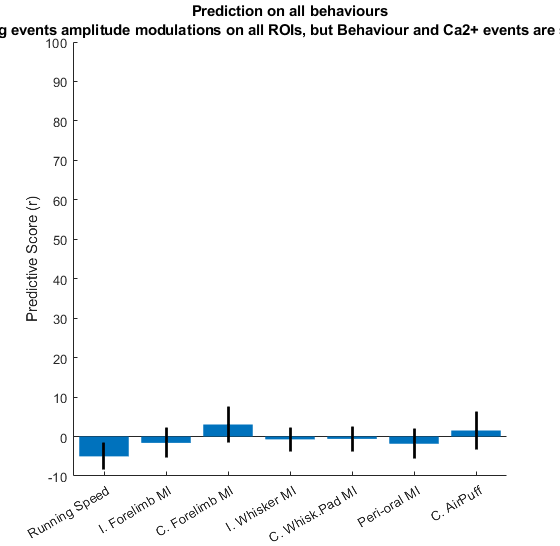

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
ml_parameters.title = {'Prediction on all behaviours',' using events amplitude modulations on all ROIs, but Behaviour and Ca2+ events are shuffled'};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters  ,...
                                             'shuffling'    ,'events'); % Shuffling of Ca2+ events

## 4.2. Spatial Shuffling

Conditions do not significantly differ from each other


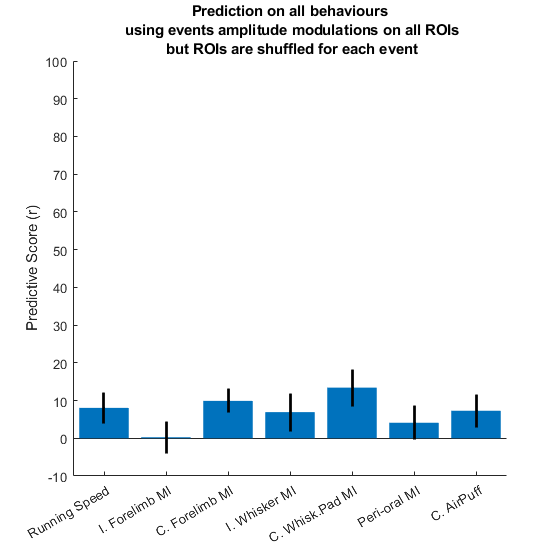

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
ml_parameters.title = {'Prediction on all behaviours';' using events amplitude modulations on all ROIs';' but ROIs are shuffled for each event'};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             ml_parameters  ,...           ,...
                                             'shuffling'    ,'ROIs');  % Shuffling of modulation across ROis during a same event

% modulation_variable_type = 1:100:15000 % mimics the slow baseline drift measurement
% need to convert the time points t into amplitudes for valid ROIs, then
% feed this to variable_type
% below is just a first approx/ball park estimate:
% tt = find(obj.get_tp_for_condition('peaks'))
% num_ev = numel(vertcat(obj.event.peak_time{:})); %could use this or several other of the obj.event outputs to get # of events
% % rand_timepoints = sort(tt(randi(numel(tt),1,num_ev)))

## 4.3. Trial Shuffling

% % This swaps the entire behaviour data, per block of 1 trial, so that it decouple behaviour and calcium
% % (this is differ from {'shuffling','events'} option of ML that shuffle individual events).
% 
% ml_parameters.title = {'Prediction selected behaviours',[' with ',num2str(round(obj.shuffling_block_size * nanmedian(diff(obj.t)),1)),'s block shuffling'],' using events amplitude modulations on all ROIs'};
% results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                              behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                              ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                              ml_parameters  ,...
%                                              'shuffling'  ,'behaviours');  
% % figure();plot(obj.rescaled_traces(:,77));hold on;scatter(viridis, obj.rescaled_traces(variable_type,77),'r','filled')


## 4.4 ROI Groups Shuffling

## On randomized groups of ROIs

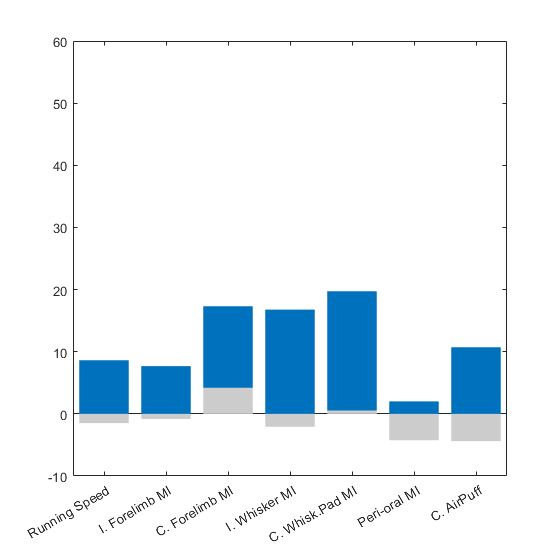

Index in position 1 exceeds array bounds.

Error in bar_chart (line 164)
            errorbar(x(1,:)',meanvalue,sem_values,'k','linestyle','none','LineWidth',2,'CapSize',0);hold on;

Error in predict_behaviours (line 170)
    [meanvalue,~, fig_handle, stats, values] = bar_chart(results, '

All_R           = {};All_values = {};All_stats = {};
gp_idx          = 0;
results  = {};
for condition = {'highest_phate', 'strong_phate', 'clusters', 'all'}
    All_R           = {};All_values = {};All_stats = {};
    gp_idx = gp_idx + 1;
    switch condition{1}
        case 'highest_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 0;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);      
        case 'strong_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = -5;   % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true); 
        case 'clusters'
            obj.cluster_factors('dbscan',-5);
            ROI_selection   = obj.dimensionality.clust_groups;        
        case 'all'
            ROI_selection   = [];        
    end

    ml_parameters.title = {'Prediction on all behaviours',[' using events amplitude modulations on randomized ',strrep(condition{1},'_',' '),' ROIs']};
    [results{gp_idx},~,~, All_R{gp_idx}, All_values{gp_idx}, All_stats{gp_idx}] = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                 behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                 ml_parameters  ,... % see defaults at the top); 
                                                 'save'         , false, ...
                                                 'randomize_ROIs', -1) ;   
    save([folder_to_use, '_ML_individual_clusters'],'results','All_R', 'All_values', 'All_stats','condition','-v7.3')
end

## 4.5 Disabling Block Shuffling

ROI_selection       = [];
ml_parameters.title = {'Prediction on all behaviours',' when NOT using block shuffling'};
results             = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                            behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                            ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                            ml_parameters  ,... %
                                            'block_shuffling' ,false); 

# 5. Introducing Time Lag

## 5.1. Time lag for all ROIs

if ~precompute_max_info
    % Extract behaours first to prevent doing it every time inside the for-loop
    extracted_beh   = prepare_behaviour_data(obj, behaviours);
    ROI_selection   = [];
    R               = {};
    
    %% Run simulation for every lag value
    for lag_idx = 1:numel(lag_list) 
        lag_idx
        lag = lag_list(lag_idx);
        ml_parameters.title = {'Prediction on all behaviours',[' using events amplitude modulations on all ROIs with a lag of ',num2str(abs(round(lag/sr,2))),' s']};
        
        if ~isempty(phase)
            condition   = {['peaks_subtracted','_lag',num2str(lag)], valid_tp}  ;   % 'peak_subtracted' or any other set of conditions / timepoints
        else
            condition   = ['peaks_subtracted','_lag',num2str(lag)]  ;   % 'peak_subtracted' or any other set of conditions / timepoints
        end
        [results,~,~, R{lag_idx}, values{lag_idx}, stats{lag_idx}]       = predict_behaviours(obj,...
                                                                                                     condition       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                                                     extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                                                                     ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                                                     ml_parameters  ,... % see defaults at the top); 
                                                                                                     'save',false   ,... % If true, results are saved automatically
                                                                                                     'savefig',false,... % Save figure. If you set a path, the figure is saved there
                                                                                                     'N_iter',N_iter_for_lag,...
                                                                                                     'rendering', false);  
    end
    
    %% Plot lag results
    [fig_handle, fig_handle_cross] = plot_lag_chart(R, lag_list, sr, behaviours, extracted_beh);
    save_myfig(fig_handle,[folder_to_use, ' All ROIs with time lag'],{'png','pdf'})
    save_myfig(fig_handle_cross,[folder_to_use, ' behaviours crosscorrelation during full recording'],{'png','pdf'})
    
    save([folder_to_use, '_lag_All_ROIs'],'R','lag_list', 'values', 'stats','sr','groups','-v7.3'); % Not saving reesults. it's too big
end

## 5.2. Time lag for High Phates

N_phates        = 3;    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes

try
    ROI_selection = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    ROI_selection = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional, true);
end

close all

% Extract behaours first to prevent doing it every time inside the for-loop
extracted_beh   = prepare_behaviour_data(obj, behaviours);
R               = {};

%% Run simulation for every lag value
for lag_idx = 1:numel(lag_list) 
    lag_idx
    lag = lag_list(lag_idx);
    if ~isempty(phase)
        condition   = {['peaks_subtracted','_lag',num2str(lag)], valid_tp}  ;   % 'peak_subtracted' or any other set of conditions / timepoints
    else
        condition   = ['peaks_subtracted','_lag',num2str(lag)]  ;   % 'peak_subtracted' or any other set of conditions / timepoints
    end
    ml_parameters.title = {'Prediction on all behaviours',' using events amplitude modulations on highest Phates',[' with a lag of ',num2str(abs(round(lag/sr,2))),' s']};
    [results,~,~, R{lag_idx}, values{lag_idx}, stats{lag_idx}]       = predict_behaviours(obj,...
                                                                         condition       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                         extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                                         ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                         ml_parameters  ,... % see defaults at the top); 
                                                                         'save',false   ,... % If true, results are saved automatically
                                                                         'savefig',false,... % Save figure. If you set a path, the figure is saved there
                                                                         'N_iter',N_iter_for_lag,...
                                                                         'rendering', false, ...
                                                                         'rendering', false);  
end

%% Plot lag results
[fig_handle, fig_handle_cross] = plot_lag_chart(R, lag_list, sr, behaviours, extracted_beh);
save_myfig(fig_handle,[folder_to_use, ' High Phates with time lag'],{'png','pdf'})

save([folder_to_use, ' lag_High_phates'],'R','lag_list', 'values', 'stats','sr','groups','-v7.3'); % Not saving results. it's too big

# 6. Focusing on specific epochs and all trace

extracted_beh   = prepare_behaviour_data(obj, behaviours);

events_tp       = find(obj.get_tp_for_condition('peaks'));
ROI_selection   = [];

% Note : You cannot test trigger by filtering out all triggers
close all
phase_list = {'Recording','free', 'whisker', 'puff'}; %recording will do all
for gp_idx = 1:numel(phase_list)
    R               = {};
    phase           = phase_list{gp_idx};
    in_phase        = cellfun(@(x) any(contains(x, phase,'IgnoreCase',true)), obj.logs); % puff, free, whisker
    valid_tp        = false(size(obj.t));
    starts          = cumsum([1, obj.timescale.tp])
    for trial = 1:numel(in_phase)
        if in_phase(trial)
            valid_tp(starts(trial):(starts(trial+1)-1)) = true;
        end    
    end
    
    for lag_idx = 1:numel(lag_list)   
        lag = lag_list(lag_idx);
        
        condition   = {['peaks_subtracted','_lag',num2str(lag)], valid_tp}  ;   % 'peak_subtracted' or any other set of conditions / timepoints

        ml_parameters.title = {'Prediction on all behaviours',' using events amplitude modulations on all ROIs',[' with a lag of ',num2str(abs(round(lag/sr,2))),' s during the ',phase,' Phase']};
        [results,~,~, R{lag_idx}, values{lag_idx}, stats{lag_idx}]            = predict_behaviours(obj,...
                                                                condition       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                                extracted_beh, ...%,'encoder','BodyCam_L_whisker'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                                ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                                ml_parameters  ,... % see defaults at the top); 
                                                                'save',false   ,... % If true, results are saved automatically
                                                                'savefig',false,... % Save figure. If you set a path, the figure is saved there
                                                                'N_iter',N_iter_for_lag,...
                                                                'rendering',false);  
    end
    
    save([folder_to_use, ' lag_all_ROIs during the ',phase,' Phase'],'R','lag_list', 'values', 'stats','sr','groups','-v7.3'); % Not saving results. it's too big
        
    %% Plot lag results
    [fig_handle, fig_handle_cross] = plot_lag_chart(R, lag_list, sr, behaviours, extracted_beh);
    save_myfig(fig_handle,[folder_to_use, 'Prediction on all behaviours, using events amplitude modulations on all ROIs during the ',phase,' Phase'],{'png','pdf'})
    save_myfig(fig_handle_cross,[folder_to_use, ' behaviours crosscorrelation during the ',phase,' Phase'],{'png','pdf'})
    close all
end



# 7. Beta Coefficents

## 7.1 Beta coef for single behaviour

% % Run Prediction for a specific behaviour
% % Note that you need to get the beta coefs for the entire tree, or it can
% % be complicated to display
% ROI_selection       = [];
% results       = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                              method         ,... % 'linear' or 'svm'
%                                              modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                              {'encoder'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                              ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                              N_iter         ,... % N iterations
%                                              false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
%                                              'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
%                                              'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
%                                              'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
%                                              'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
%                                              'kfold', KFold             ,...
%                                              'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title
% 
% all_scores = extract_ML_coefs(obj, results, true, 'beta')

## 7.2 Display Beta coefs

% % Run with deifferent lags, and display beta coef in an animation
% extracted_beh   = prepare_behaviour_data(obj, 'trigger');
% 
% lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
% lag_list        = unique(round(lag_list * sr));
% R               = {};
% 
% for lag_idx = 1:numel(lag_list) 
%     lag_idx
%     lag = lag_list(lag_idx);
%     [results,~,~, R{lag_idx}, values{lag_idx}, stats{lag_idx}]       = predict_behaviours(obj,modulation_variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
%                                                  method         ,... % 'linear' or 'svm'
%                                                  ['peaks_subtracted','_lag',num2str(lag)],...
%                                                  extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
%                                                  ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
%                                                  1              ,... % N iterations
%                                                  false          ,... % if ~false, random groups are generated matching "ROI_selection" size. If 1 we use all ROis, if -1 we only use ROIs not in ROI_selection
%                                                  'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
%                                                  'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
%                                                  'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
%                                                  'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
%                                                  'kfold', KFold             ,...
%                                                  'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title
% 
%     all_scores{lag_idx} = extract_ML_coefs(obj, results, false, 'beta');
% end
% 
% %% Note : small video of the beta coefs + predictive score for a giver behaviour, to capture with OBS 
% values = cell2mat(cellfun(@(x) nanmean(x{1})', all_scores, 'UniformOutput', false))';
% for lag_idx = 1:numel(lag_list) 
%     figure(123); clf();
%     ax1 = subplot(1,2,1);beh_idx = 1;
%     obj.ref.plot_value_tree(values(lag_idx,:), cell2mat(results{1}.used_ROIs),'',['encoder with lag = ',num2str(lag_list(lag_idx))],'',ax1);
% %     pause(0.3)
%     ax2 = subplot(1,2,2);cla();beh_idx = 1;
%     a = cell2mat(R);x = lag_list/sr;
%     patch([x,fliplr(x)], [a(beh_idx, :), zeros(size(a(beh_idx, :)))], 'k')
%     title(strrep(extracted_beh.original_behaviour_list{beh_idx},'_',' '));xlabel('Lag (s)');ylabel('Prediction score');
%     xline(x(lag_idx),'b-');
%     xline(0,'r--');pause(0.1)
% end
% %obj.animate_experiment(values, '', cell2mat(results{1}.used_ROIs))

% 
% for sm = [0,1,10]
%     extracted_beh   = prepare_behaviour_data(obj, behaviours,true, sm);
%     figure();clf();
%     tiledlayout('flow');
%     for beh = 1:size(extracted_beh.raw_behaviours, 1)
%         axes(beh) = nexttile    ;
%         title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
%         plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
%         xlabel('Lag (s)');xline(0,'r--')
%     end
% end

% for beh = behaviours
% %beh = 'L_forelimb';
%     raw_beh = get_behaviours(obj, beh{1}, false, true, true, false);
%     raw_beh = raw_beh{1};
%     test = cellfun(@(x) x.value, raw_beh, 'uni', false);
%     test = vertcat(test{:});
%     test(isnan(test)) = 0;
%     figure();plot(xcorr(vertcat(test), 150));title(beh{1})
% end

## Setp 1 identify a group of Phate discovered ROIs that have a strong specific tuning

% 
% 
% 
% Phate_nb = 5;
% figure();title(['Phate # ',num2str(Phate_nb)])
% plot(obj.t,nanmean(obj.rescaled_traces(:,groups{Phate_nb*2-1}),2) - obj.global_median_rescaled,'g'); hold on;
% set(gcf, 'Color', 'w'); hold on;
% plot(obj.t,nanmean(obj.rescaled_traces(:,groups{Phate_nb*2}),2) - obj.global_median_rescaled,'r'); hold on;
% set(gcf, 'Color', 'w'); hold on;
% [~,~,trig] = obj.get_behaviours('trigger'); hold on;
% plot(obj.t,trig.value,'k','LineWidth',2);legend({'Positive Phate','Negative Phate'});
% xlim([1100,1500]);
% ylim([-10,20])

5. Control based on the baseline behaviour

- h-word

- test if Ca is dirtributed normally (it should be, almost)

% % run some (n = 16) key controls (e.g. do ML fo all ROIs with peaks_subtracted, raw_peaks, raw, raw_queit, quiet_subtracted
% % plus a few shuffles where most relevant)
% 
% v = obj.rescaled_traces(obj.get_tp_for_condition('peaks'), :);
% figure();hist(v(:),100);title('distribution of rescaled events amplitude (all ROIs)')
% figure();hist(reshape((v - obj.global_median_rescaled(obj.get_tp_for_condition('peaks'))),[],1),100);title('distribution of median subtracted rescaled events amplitude (all ROIs)')
% 
% 
% 
% % plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
